# Interference of light

[EE551 - Spring 2021 - Tutorial 5 - Interferometry ](https://github.com/SrikanthS-IIT/EE551-Tutorials-Spring2021/blob/main/EE551-Spring%202021-Tutorial5_Interferometry.mlx)© 2021 by [Srikanth Sugavanam ](https://www.srikanthsugavanam.com/)is licensed under [CC BY-NC 4.0    ](http://creativecommons.org/licenses/by-nc/4.0/?ref=chooser-v1)

## Finding the right sampling frequency

In class we discussed how the interference of two plane waves can give rise to a sinusoidal interference pattern -


$$I=2I_0 \left(1+\cos \;2\pi u\;x\right),$$


where $u$ is the spatial frequency of the interference pattern, and is given by the relation


$$u=\cos \;\alpha \;/\lambda \;,$$


such that the inverse of this quantity is essentially the spatial period of the fringe as projected on the x-axis.

$\alpha \;$is the angle between the interfering plane waves. As the angle between the plane waves increases, so does the modulation frequency. This means if we want to simulate the fringe pattern, we should also adequately sample it. Otherwise, we will run into aliasing errors, resulting in incorrect results. As we shall see, this will result in trade-off between the largest angle $\alpha \;$for which we can simulate the interference pattern, and the spatial size of the window of observation. 

To determine the sampling frequency required to correctly reproduce the fringe pattern, we can use the Nyquist criterion. This says that the sampling frequency chosen should be at least twice that of the signal frequency itself. To be on the safe side, we can extend it to four times. The code snippet below plots the requisite sampling frequency, normalized by the wavelength of light being used. The reason for this normalization will become clearer as we proceed; the advantage however is evident here too - this will be discretization of the array we will need to define, regardless of the wavelength of light we use. 

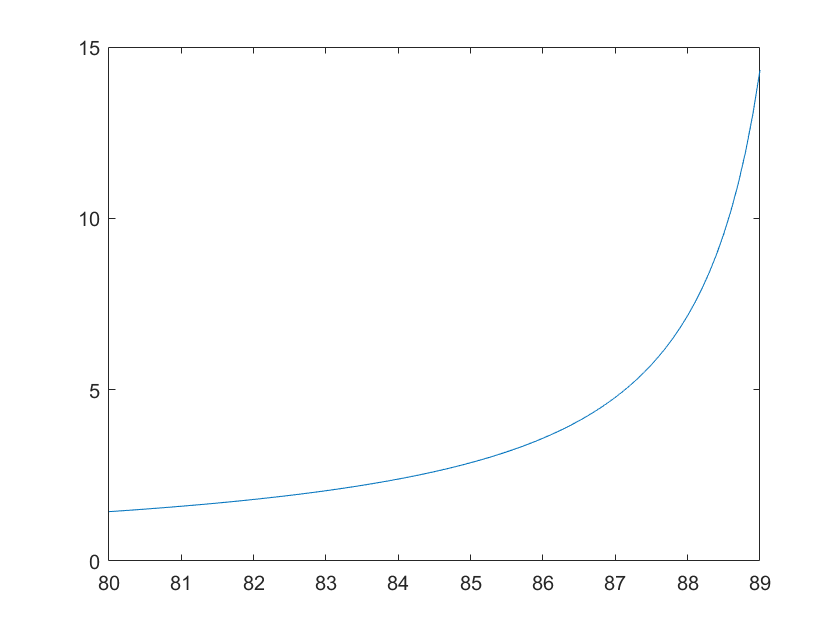

lambda = 632.9E-9;
a = 80:0.1:89;
u = (cosd(a)/lambda);
plot(a,1./u/4/lambda);

Note that here we are taking a geometry where one of the plane waves is parallel to the x-y plane, and has a k vector along the z direction, while the other plane wave is also normal to the x-z plane, while its k-vector makes a small angle with the z direction. 

For the first wave thus, we can write the directional cosines as 


$$\alpha =\frac{\pi }{2},\beta =\frac{\pi }{2},\gamma =0,$$


while for the second plane wave, we can write the directional cosines as


$$\alpha =\frac{\pi }{2},\beta =\frac{\pi }{2}-\delta \;,\gamma =0\ldotp$$


For the purposes of illustration, we will however limit ourselves to small angles ($\delta <2^0 \times \frac{\pi }{{180}^{0\;} }$). 

The x axis in the above graph is $\beta$. From this graph, we see that if we want to simulate fringe patterns for interfering plane waves that make a relative angle of say 87 degrees, we will need a spatial sampling frequency of at least 4-5 pixels, regardless of the wavelength of light being used.   

## Simulating two-beam plane wave interference

The code snippet below plots the analytically derived expression of the two-beam plane wave interference pattern observed at a given z-location (arbitrarily taken as zero without any loss of generality). 

Study the code to see how the spatial co-rdinate variable $x$ is defined. We use the same normalization trick that we used in the previous tutorial on Gaussian beams. Also, note how the plot shows $x$ in real-world values (mm). This can also be presented in normalized co-ordinates. ***You can now also calculate roughly whether a 5 MP CCD of dimensions 3 cm by 2 cm will be able to resolve the fringe pattern!***

In the code below, put different values of $\alpha \;$and change the value of the discretization of $x$ to see how it affects the results. 

**CAUTION** - Be careful not to increase the size of the $x$ vector beyond 5000 elements, as it may slow down execution time. 

I_0 = 1;
lambda = 632.9E-9;
a = 89.99*pi/180;
u = cos(a)/lambda;
x = [-1E4:10:1E4]*lambda;
size(x)

ans =            1        2001


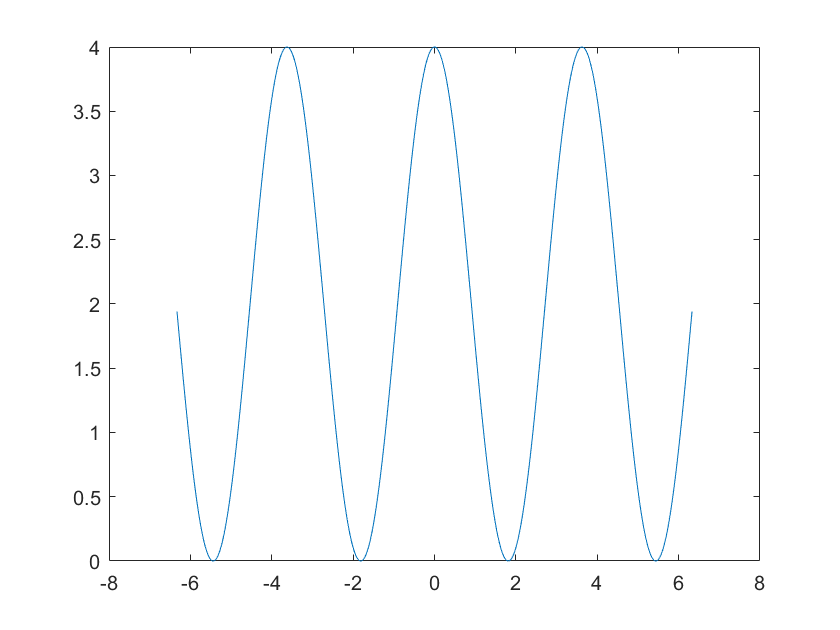


I = 2*I_0*(1 + cos(2*pi*u*x));

figure(1);
plot(x*1E3,I);

Note how even a small change in the angle $\alpha \;$can change the fringe pattern drastically. 

***Check the following***

- Compare this with the resolution offered by a common protractor (${\sim 1}^0$!). 

- Now you can start equating this angular deviation to a linear translation effected by a micrometer screw. 

- What is the typical length resolution offered by such screws? How does that compare to the resolution offered by the above interferometric method? 

## Moving to two dimensions

We will now scale up our code so that we can account for two dimensions. This way we can match our codes to what one usually observes in experiment using a CCD camera. 

For getting a better spatial resolution (1 pixel), we will reduce the lateral dimension of the field. This is still appreciable enough to understand the results, and also to implement in experiment. 

Note the use of the *meshgrid* command. Check what it does using the MATLAB help online. 

x = [-0.1E4:1:0.1E4]*lambda;
vec_x = x;
vec_y = [-0.1E4:1:0.1E4]*lambda;
[x,y] = meshgrid(vec_y,vec_x);
size(x)

ans =         2001        2001


**CAUTION** - Limit the size of the grid to below 5000 x 5000 elements. I am keeping it around 2000. If the computer slows down, reduce this size further. 

## Two-beam plane wave interference - in 2D

We will now implement two-beam plane wave interference in 2D. This will allow us to adjust the relative tilt between the beams, which is usually encountered in interferometric configurations like the Twyman Green interferometer. 

For ease of understanding, we will fix one of the beams to propagate normally along the x-axis. You will then adjust the inclination of the second beam with respect to the first to observe the effect of interference. 

Remember that you will get strange results if you increase the angle of inclination beyond that afforded by the sampling resolution. 

### Using user-defined functions

You will generate several plane waves using the function PlaneWave. Go now to the end of this file to see how the function is defined. 

The code snippet below shows how we can use the function to define a plane wave moving along the z-axis. We will call this plane wave E_ref.

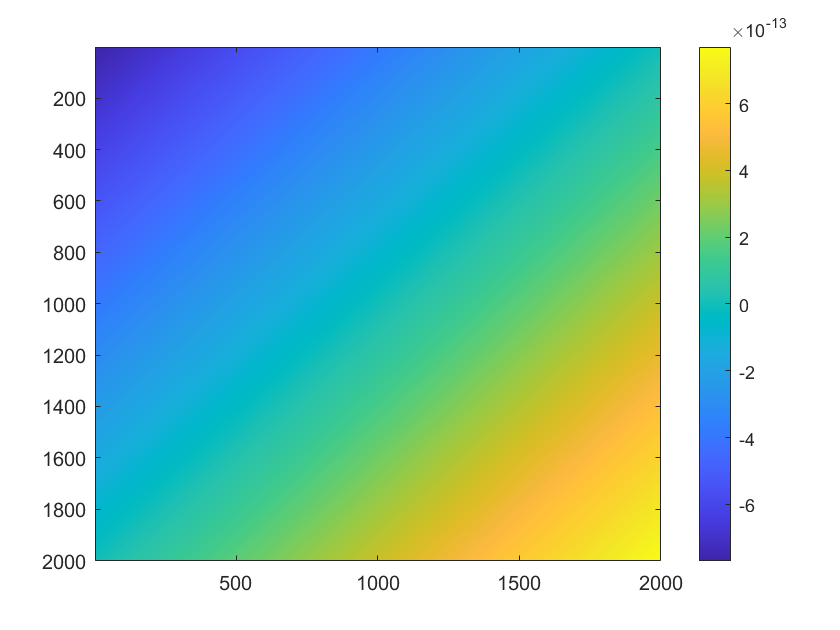

%Using the ones function to define a plane wave with unit amplitude over the meshgrid x,y 
A1 = ones(length(x),length(y));

%Defining the k-vector angles
a = 90*pi/180;
b = 90*pi/180;

%Calling the PlaneWave function
E_ref = PlaneWave(A1, x, y, a, b, lambda);

imagesc(angle(E_ref));colorbar

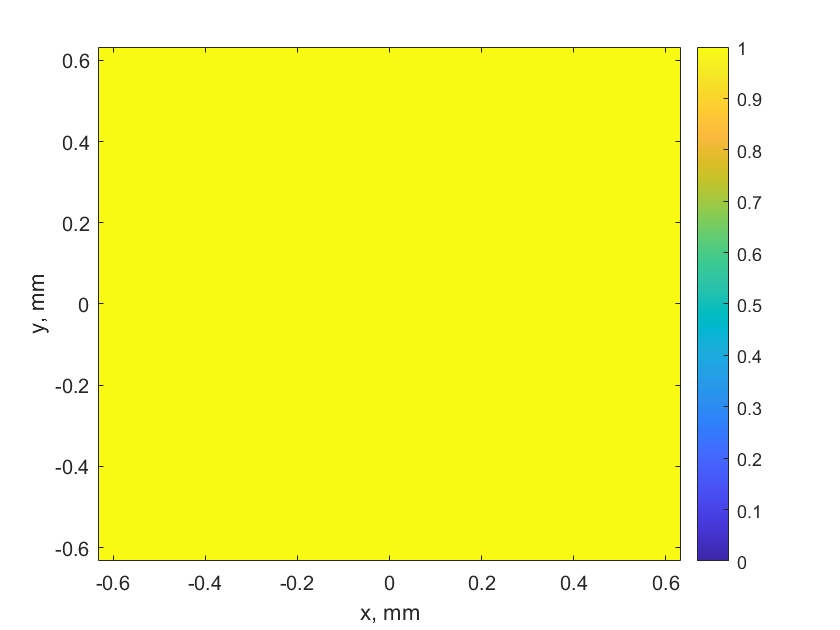

%Verifying the result - amplitude should be one throughout.
figure;
imagesc(vec_x*1E3, vec_y*1E3, abs(E_ref).^2);
xlabel('x, mm');
ylabel('y, mm');
colorbar;
set(gca,'Clim',[0 max(max(abs(E_ref))).^2])
set(gca,'Ydir','Normal')

### Task 1 - Defining the test beam

Using the example above, define a plane wave E_test of unit amplitude moving at an angle 0.1 degrees wrt the z-axis. The size of the grid will remain the same. 

%Insert appropriate values...
A2 = A1;
a = 89.9*pi/180;
b = 90*pi/180;

E_test= 0;

E_test = PlaneWave(A1,x,y,a,b,lambda);

### Task 2 - Visualizing the interference pattern.

Write a code to visualize the interference pattern between E_test and E_ref. 

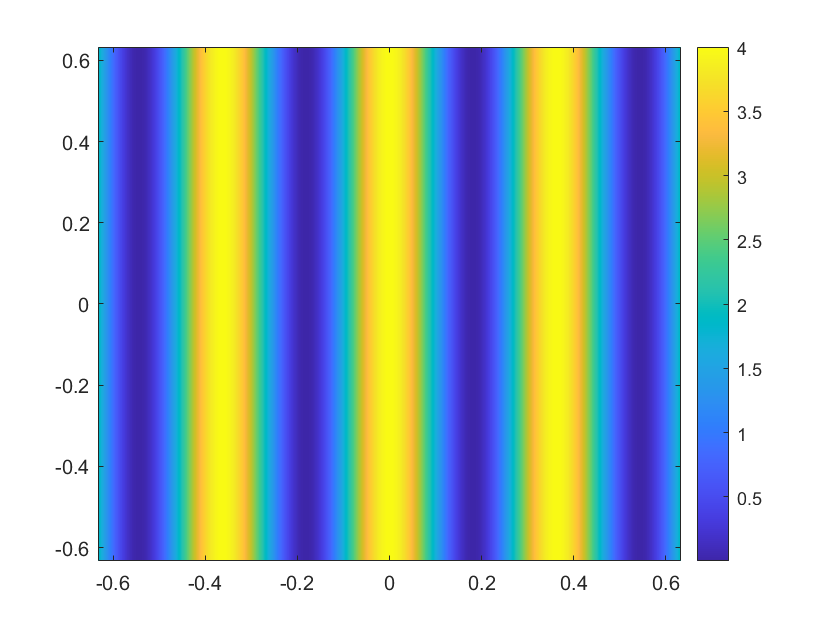

I = (abs(E_test + E_ref)).^2;
% I = I/max(max(I));

imagesc(vec_x*1E3,vec_y*1E3,I);colorbar;
set(gca,'Ydir','normal');


% plot(vec_x,I(floor(length(vec_x)/2),:));

## Spherical wave interference

### Interference between spherical and plane wave

Using the codes above, we will now write the code for visualizing the interference pattern between a reference plane wave, and a spherical wave centered at the origin. 

%Tuning the meshgrid...
x = [-0.1E3:0.1:0.1E3]*lambda;
vec_x = x;
vec_y = [-0.1E3:0.1:0.1E3]*lambda;
[x,y] = meshgrid(vec_y,vec_x);

size(x)

ans =         2001        2001


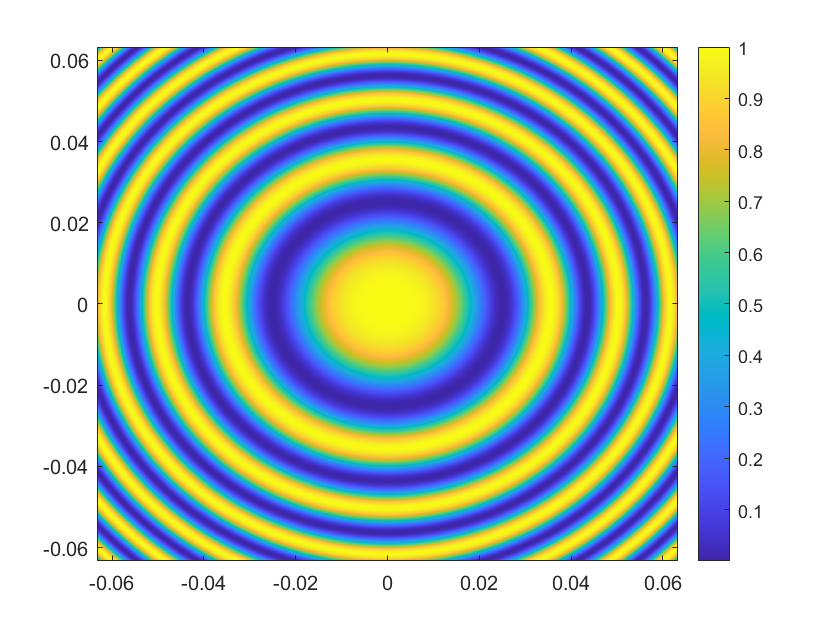

A1 = ones(length(vec_x),length(vec_x));

%Distance to screen - 1 mm
z = 1E-3;

%Reference plane wave with accumulated phase over distance travelled to
%screen
E_ref_2 = A1.*exp(1i*2*pi/lambda*z);

%Distance to a point on the screen
r = sqrt(z^2 + (x.^2 + y.^2));

%Spherical wave
E2 = A1./r.^2.*exp(1i*2*pi/lambda*r);

% Paraxial approximation
% E2 = A1./r.^2.*exp(1i*2*pi/lambda/z/2*(x.^2 + y.^2));

%Normalizing the amplitude of the spherical beam
E2 = E2/abs(E2(floor(length(vec_x)/2),floor(length(vec_y)/2)));

%Interference pattern
%I = abs(E_ref_2).^2 + abs(E2).^2 + 2*abs(E_ref_2).*abs(E2).*cos(??);
I = (abs(E_ref_2 + E2)).^2;
I = I/max(max(I));

imagesc(vec_x*1E3,vec_y*1E3,I);
set(gca,'Ydir','normal');
% set(gca,'Clim', [0 1]);
colorbar;

### Task 1 - Understanding the spherical wave implementation

- Verify if the paraxial approximation is met for this spherical wave. 

- Comment the normalization code and run the code. What is happening?

- Verify that the abs function gives the same output as the theoretically expected output, when you substitute for the angle in the cos function. 

- Change the value of z to 100$\lambda$, 100 cm, 1 m. Does it match your expectations?

- Optional - this will be useful for the next exercise. Like the function PlaneWave, write a user-defined function for implementing spherical waves.

### Task 2 - Young's experiment

Now that you know how to define a spherical wave, simulate the Young's experiment. 

In this experiment, a spherical wave coming from a point source is incident on a screen with two pinholes that is symmetrically located with respect to the point source. These two pinholes by Huygen's principle can then be considered to become a new source of spherical waves, with the important characteristic that owing to the symmetry of the configuration, the two sources can be considered to be mutually coherent. 

Considering the above geometry (this is your hint!). simulate the Young's experiment. Specifically, 

- Plot the interference pattern at a given distance from the source (you can start the above defined values for the meshgrid and the distance z).

- Verify that the fringe width is the same as that predicted from expressions obtained from geometrical considerations.

- Obtain the fringe distribution at an arbitrary location away from the center of the screen. 

## User-defined functions

Place your user-defined functions here. 

function E1 = PlaneWave(A1,x,y,p,q,lambda)
%Here the name of the function is PlaneWave. This function will take in
%functional arguments A1, u, v, and do some computations using these
%variables and return the plane wave E1.

%Here, A1 is two-dimensional grid with an amplitude value at each point. a
%and b are the angle the wave vector makes with the x and y axis
%respectively. 

%Defining the spatial frequencies...
u = cos(p)/lambda;
v = cos(q)/lambda;

%Formulating the plane wave
E1 = A1.*exp(1i*2*pi*(u*x + v*y));
end